Created on: 8/02/2024

Author: Ankana Sadhu

Roll No.:CH21S025

X= [1 3 5;8 -1 6];

## Singular Value Decomposition:


$$X=\left(U\Sigma V^T \right)$$


Where U and V are the left and right singular vectors respectively.

$\Sigma$ is the Singular matrix

Using the above equation we can write:

$\[
X^T X = (U\Sigma V^T)^T (U\Sigma V^T) = V \Sigma^T U^T U \Sigma V^T = V \Sigma^T \Sigma V^T \Rightarrow (X^T X) V = V \Sigma^T \Sigma
\]
$ =$V\;\Lambda$                         

 
$$V^T V=I\;\mathrm{and}\;U^T U=I\;\mathrm{since},X^T X\;\mathrm{and}\;{\mathrm{XX}}^{T \;}$$


are symmetric matrices which by property have orthogonal eigen vectors,

 these on normalizing become orthonormal vectors. 

['eig' MATLAB routine normalizes by default]

[V, Lambda]= eig (X'*X)

V =     0.4785    0.5048    0.7185
    0.7074   -0.7064    0.0251
   -0.5202   -0.4962    0.6951


Lambda =     0.0000         0         0
         0   19.8959         0
         0         0  116.1041



$$\[
X X^T = (U \Sigma V^T) (U \Sigma V^T)^T = U \Sigma V^T (V \Sigma^T U^T) = U \Sigma \Sigma^T U^T \Rightarrow (X X^T) U = U \Sigma \Sigma^T
\]
$$

$$=U\lambda$$


[U, lambda]= eig (X*X')

U =    -0.9182    0.3962
    0.3962    0.9182


lambda =    19.8959         0
         0  116.1041


$\Sigma$ is of size 3 X 2 and has only diagonal elements 

Points to note:

SVD provides singular values in descending order

Corresponding left and right singular vectors are also given the same orde.

Sigma_bar= diag([Lambda(3,3)^0.5, Lambda(2,2)^0.5,0])

Sigma_bar =    10.7752         0         0
         0    4.4605         0
         0         0         0


Sigma=Sigma_bar(1:2,:)

Sigma =    10.7752         0         0
         0    4.4605         0


V=[V(:,3), V(:,2), V(:,1)]

V =     0.7185    0.5048    0.4785
    0.0251   -0.7064    0.7074
    0.6951   -0.4962   -0.5202


U=[U(:,2),U(:,1)]

U =     0.3962   -0.9182
    0.9182    0.3962


[u,sigma, v]=svd(X)

u =     0.3962    0.9182
    0.9182   -0.3962


sigma =    10.7752         0         0
         0    4.4605         0


v =     0.7185   -0.5048   -0.4785
    0.0251    0.7064   -0.7074
    0.6951    0.4962    0.5202


We can see that a few basis are -1 multiples of what we have obtained using eigen value decomposition. Since, this is a factorization technique we can still derive at different $U,\Sigma \;\textrm{and}\;V$ values by using different routines. 

But, $X=\left(U\Sigma V^T \right)$ should hold always.

## Principal Component Analysis

In the data generating process we have added noise to the pure data.

% Data Generating Process
A=randn(1000,1);
A=[1.2*A*sin(20) 0.8*A*cos(20)] + randn(1000,2)*0.15;


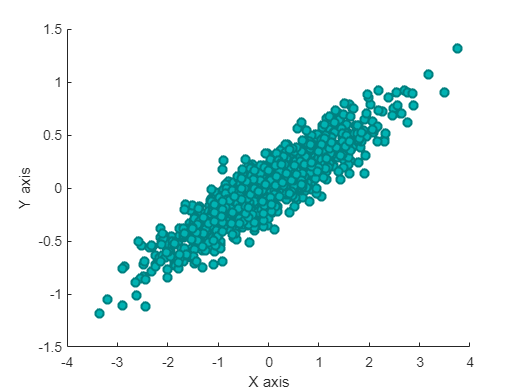

scatter(A(:,1),A(:,2),'filled','MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5);
xlabel('X axis')
ylabel ('Y axis')

Performing SVD on the noisy data

[u,sigma,v]=svd(A);
size(u)

ans =         1000        1000


size(v)

ans =      2     2


$\Sigma \;$signifies the spread of data along each basis spanning the columnspace.

sigma

sigma =    35.5824         0
         0    4.5781
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


On eliminating the basis with lower singular value we get the projection of the data along the maximum spread.

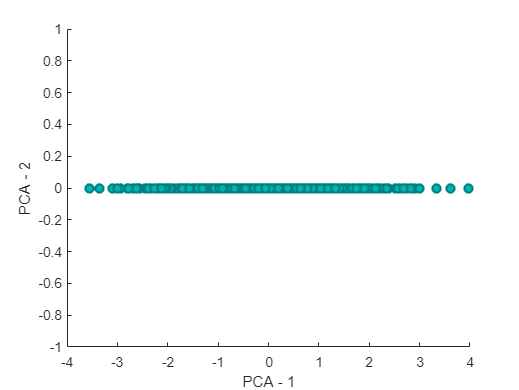

A_reduced= A*v(:,1);
scatter(A_reduced, zeros(1000,1), 'filled','MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5)
xlabel('PCA - 1');
ylabel('PCA - 2')

## Diagonalisation of square matrices help in manual calculation of $A^n$

X= [1 3 5;8 -1 6; 4 8 9];
X^100

ans = 1.0e+118 *

    2.6172    2.5814    4.3600
    3.3069    3.2616    5.5089
    5.6340    5.5568    9.3855


[V,Sigma]=eig(X)

V =    -0.3719    0.3963   -0.0131
   -0.4699    0.6659    0.8638
   -0.8006   -0.6321   -0.5036


Sigma =    15.5538         0         0
         0   -1.9347         0
         0         0   -4.6191


V*Sigma^100*V^-1

ans = 1.0e+118 *

    2.6172    2.5814    4.3600
    3.3069    3.2616    5.5089
    5.6340    5.5568    9.3855


Since Sigma has only 3 diagonal elemensts therefore, ${\textrm{Sigma}}^{100}$ is quite simple to calculate (each element raised to 100).  

By diagonalisation we can reduce N-1 (here, 99) matrix multiplication by just 2 matrix multiplication and one matrix inversion.

## Gradient Descent:

Find $\alpha$ such that the following equation is satisfied


$$Y=X$$

$$\alpha$$


% Data Generating Process
X=randn(1000,1);
Y=[1.2*X] + randn(1000,1)*0.15;
loss_append=[];
alpha_append=[];


$$\begin{array}{l}
\textrm{Loss}\;\textrm{fun}=\frac{1}{N}{\Sigma \left(Y-Y_{\textrm{hat}\;} \right)}^2 \\
Y_{\textrm{hat}} =X\alpha \\
\frac{\textrm{dL}}{d\alpha }=\frac{2}{N}\Sigma \left(Y-X\alpha \right)*\left(-X\right)\\
\alpha_{\textrm{update}} =\alpha -\beta *\frac{\textrm{dL}}{d\alpha }\\
\textrm{where}\;\beta =\textrm{stepsize}
\end{array}$$


alpha= [0]; %initial guess
beta=0.1;
for epochs= 1:100
    sum_fn= sum(-X'*(Y-X*alpha));
    
    alpha= alpha -beta *2*sum_fn/1000;
    Y_calc= X*alpha;
    loss= meansqr(Y-Y_calc);
    loss_append=[loss_append,loss];
    alpha_append=[alpha_append,alpha];
end


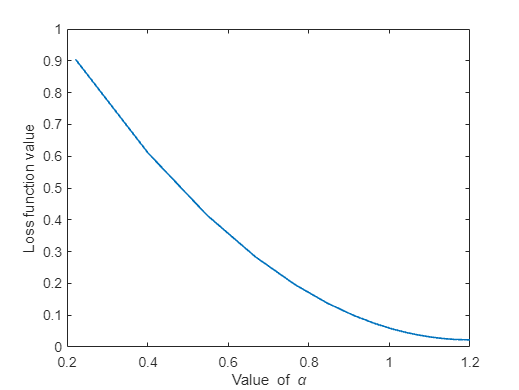

figure;
plot(alpha_append,loss_append,'LineWidth',1.2);
xlabel('Value of \alpha')
ylabel ('Loss function value')

alpha

alpha = 1.1999

Using fminunc to optmize the Mean Square Error Function

loss= @(alpha) meansqr(Y-X*alpha)

loss = function_handle with value:
    @(alpha)meansqr(Y-X*alpha)


a0=0;
fminunc(loss,a0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 1.1958

% Data Generating Process
X=randn(1000,3);
Y=[1.2*X(:,1)+0.8*X(:,2)+0.3*X(:,3)] + randn(1000,2)*0.15;
loss= @(alpha) meansqr(Y-X*alpha)

loss = function_handle with value:
    @(alpha)meansqr(Y-X*alpha)


a0=[0; 0; 0];
fminunc(loss,a0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans =     1.2010
    0.7992
    0.2951
